# Activity 4

# OFDM Modulation with the Inverse FFT

In this activity, you'll create a simple OFDM system, with an IFFT as the OFDM modulator and an FFT as the OFDM demodulator.

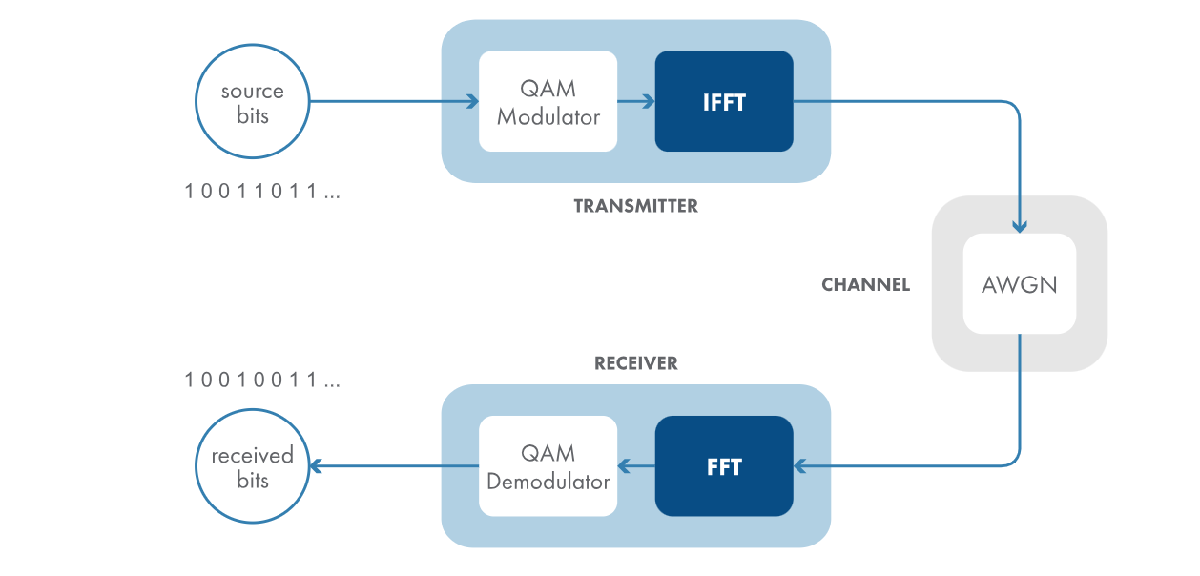

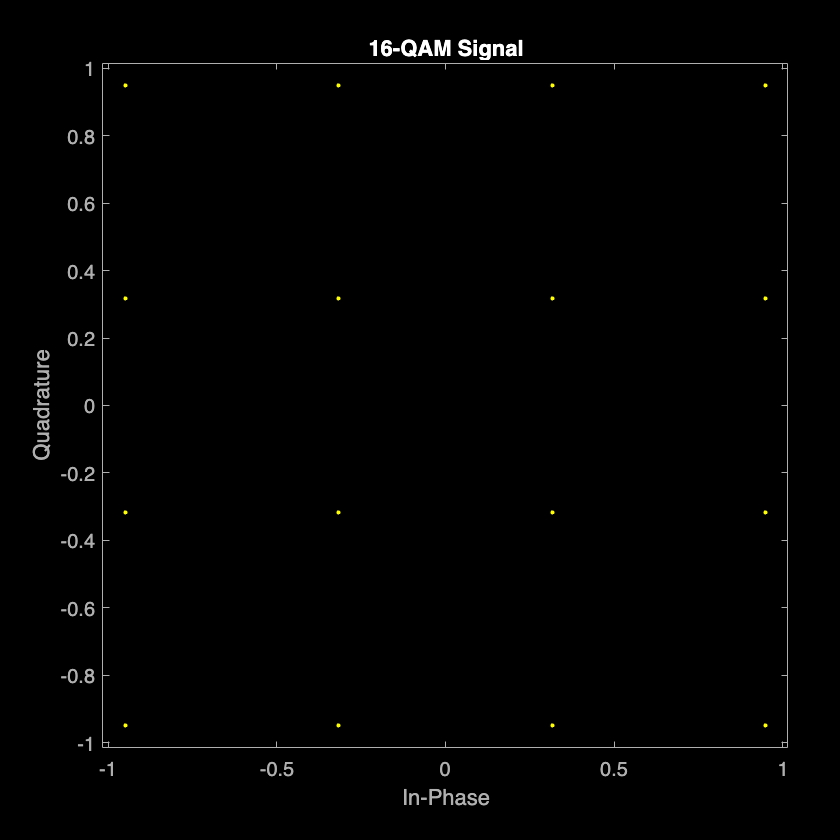

clc
close
clear

numBits = 32768;  % power of 2, to optimize performance of fft/ifft
modOrder = 16;  % for 16-QAM

srcBits = randi([0,1],numBits,1);
qamModOut = qammod(srcBits,modOrder,"InputType","bit","UnitAveragePower",true);
scatterplot(qamModOut)
title("16-QAM Signal")

Background

The `ifft` function computes the inverse discrete Fourier transform of a signal.

`sigOut` `=` `ifft``(``sig``)`

The output is the same size as the input signal.

Notice that the number of bits in the simulation has changed—it's now a power of 2, which means the length of the QAM signal is also a power of 2. The `ifft` and `fft` functions are significantly faster for signals of certain lengths, including those whose length is a power of 2.

ofdmModOut = ifft(qamModOut);

Once you've created the variable `ofdmModOut` in the script, it is sent over a noisy channel.

if exist("ofdmModOut","var")  % code runs after you complete Task 1
    SNR = 15;  % dB
    chanOut = awgn(ofdmModOut,SNR,"measured");
end

Next, in the receiver, you need to "undo" the IFFT by performing an FFT.

The `fft` function computes the discrete Fourier transform, via the fast Fourier transform algorithm.

`sigOut` `=` `fft``(``sig``)`

ofdmDemodOut = fft(chanOut);

Since the OFDM demodulator output is a 16-QAM signal, you can look at its scatter plot.

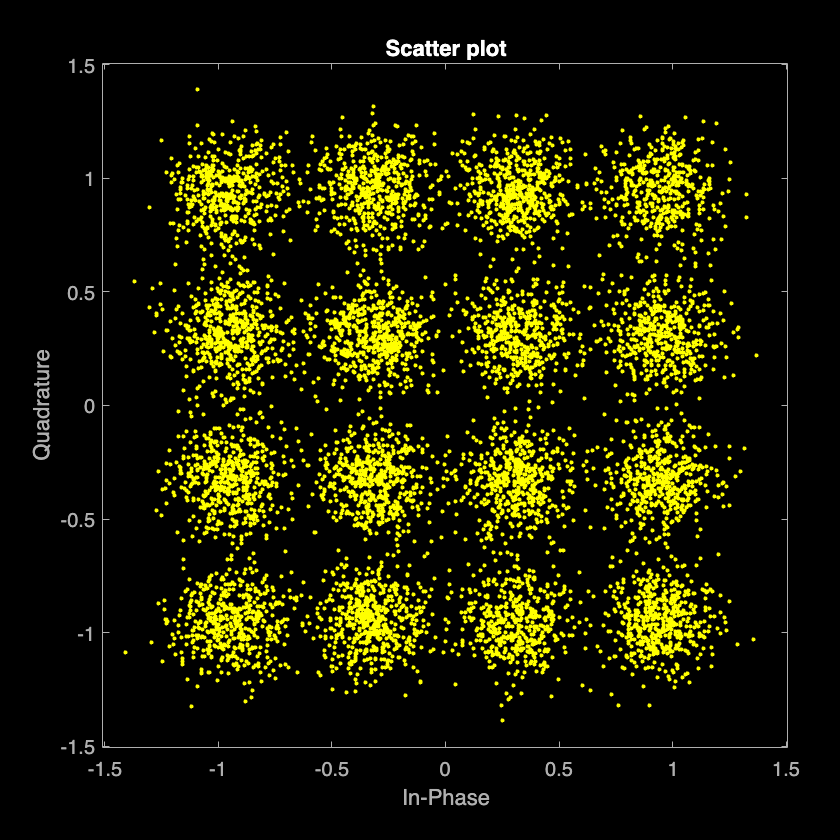

scatterplot(ofdmDemodOut)

Demodulate back into bits, then calculate the BER.

if exist("ofdmDemodOut","var")  % code runs after you complete Task 2
    qamDemodOut = qamdemod(ofdmDemodOut,modOrder,"OutputType","bit","UnitAveragePower",true);
    numBitErrors = nnz(srcBits~=qamDemodOut)
    BER = numBitErrors/numBits
end

numBitErrors = 142

BER = 0.0043

**FURTHER PRACTICE**

The signal was sent over a noisy channel, so you should expect to see some noise in the constellation. The script also calculates the BER, and you can change the value of `SNR` on line 11 to look at the link's performance.

This link performs about as well as a noisy 16-QAM link without OFDM—if you increase `SNR` to about 20, there are no bit errors.

However, you don't yet know how the link will do with a multipath channel. You'll look at this in the next activity.